clf;
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
%low pass / high pass
tf1 = tf([1],[1,1]);
tf2 = tf([1,0],[1,1]);

%low pass / high pass
tf1 = tf([1,1],[1])

tf1 =
 
  s + 1
 
Continuous-time transfer function.



tf2 = tf([1,1],[1,0])

tf2 =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



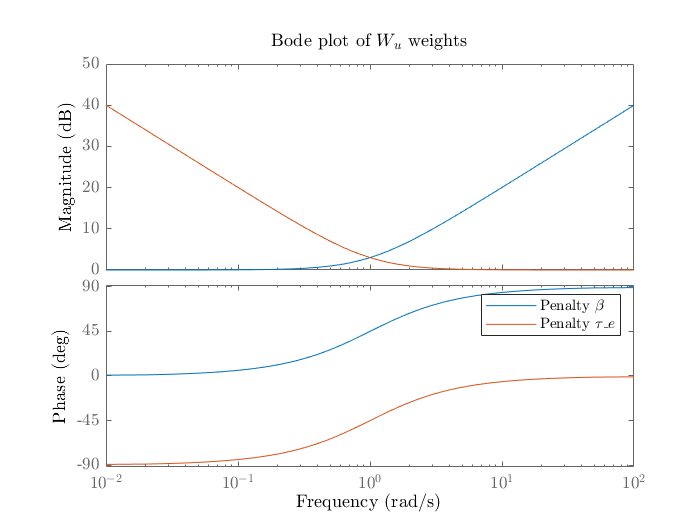


bode(tf1)

hold on
bode(tf2)
legend("Penalty $\beta$", "Penalty ${\tau}_{e}$")

xlabel('Frequency','interpreter', 'latex')
ylabel('Phase','interpreter', 'latex')
title('Bode plot of $W_u$ weights','interpreter', 'latex')
saveas(gcf, 'Figures/ch3_mimo_weights_filter.eps',  'epsc')